freq = [
100
200
300
400
500
600
700
800
900
1000
1250
1500
1750
2000
2250
2500
2750
3000
3250
3500
3750
4000
4250
4500
4750
5000
];

vout = [
0.052
0.148
0.16
0.132
0.124
0.144
0.144
0.204
0.224
0.18
0.284
0.352
0.332
0.408
0.41
0.42
0.42
0.54
0.652
0.656
0.74
0.76
0.8
0.82
0.79
0.62  
];

vin = [
0.52
0.84
1.04
0.72
0.82
1
0.72
1.04
1
0.8
0.8
0.84
0.84
0.92
0.88
0.88
0.94
1
1.04
1.04
1.1
1.1
1.1
1.1
1.1
1.1 
];

phase = [
-83.2
-143.9
-165
-171.36
-181.82
-164.9
-165
-172.32
-174.06
-176.36
-195
-217.7
-241.6
-253.2
-262.7
-285
-294
-304
-323
-348
-367
-390
-420
-445
-474.4
-510 
];

freq = [
100
200
300
400
500
600
700
800
900
1000
1250
1500
1750
2000
2250
2500
2750
3000
3250
3500
3750
4000
4250
4500
4750
5000
];

vout = [
0.256
0.232
0.176
0.16
0.152
0.152
0.164
0.168
0.184
0.188
0.244
0.272
0.248
0.208
0.236
0.212
0.224
0.256
0.3
0.316
0.34
0.356
0.36
0.372
0.332
0.264
];

vin = [
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.56
0.584
0.584
0.616
0.616
0.6
0.608
0.608
0.616
0.616
0.616
0.616
0.616
0.608    
];

phase = [
59.8
2.88
-13
-18.7
-21.8
-15.1
-13.5
-12.9
-25.3
-16.3
-37.8
-60.4
-83.7
-94
-104
-118
-133
-141
-157
-178
-198
-223
-248
-275.2
-308.1
-340.6    
];

freq = [
100
200
300
400
500
600
700
800
900
1000
1250
1500
1750
2000
2250
2500
2750
3000
3250
3500
3750
4000
4250
4500
4750
5000
];

vout = [
0.256
0.232
0.176
0.16
0.152
0.152
0.164
0.168
0.184
0.188
0.244
0.272
0.248
0.208
0.236
0.212
0.224
0.256
0.3
0.316
0.34
0.356
0.36
0.372
0.332
0.264
];

vin = [
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.552
0.56
0.584
0.584
0.616
0.616
0.6
0.608
0.608
0.616
0.616
0.616
0.616
0.616
0.608    
];

phase = [
59.8
2.88
-13
-18.7
-21.8
-15.1
-13.5
-12.9
-25.3
-16.3
-37.8
-60.4
-83.7
-94
-104
-118
-133
-141
-157
-178
-198
-223
-248
-275.2
-308.1
-340.6    
];

tran = vout./vin;

disp(tran)

    0.1000
    0.1762
    0.1538
    0.1833
    0.1512
    0.1440
    0.2000
    0.1962
    0.2240
    0.2250
    0.3550
    0.4190
    0.3952
    0.4435
    0.4659
    0.4773
    0.4468
    0.5400
    0.6269
    0.6308
    0.6727
    0.6909
    0.7273
    0.7455
    0.7182
    0.5636



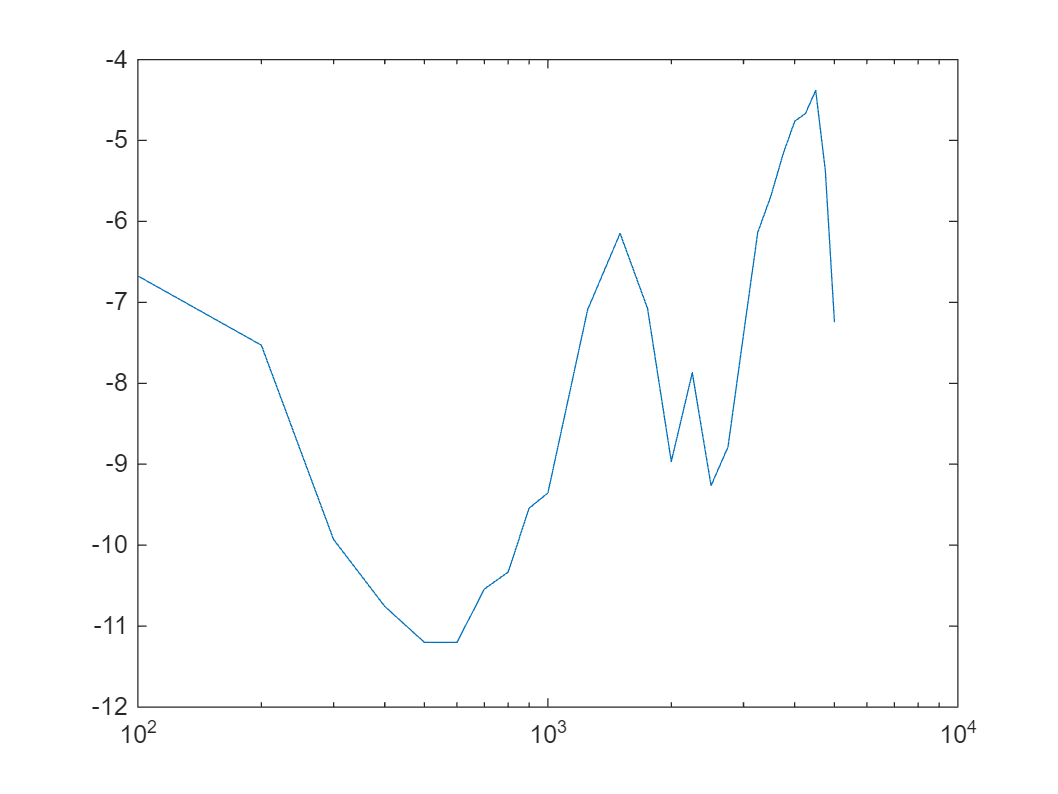

semilogx(freq, 20*log10(tran));

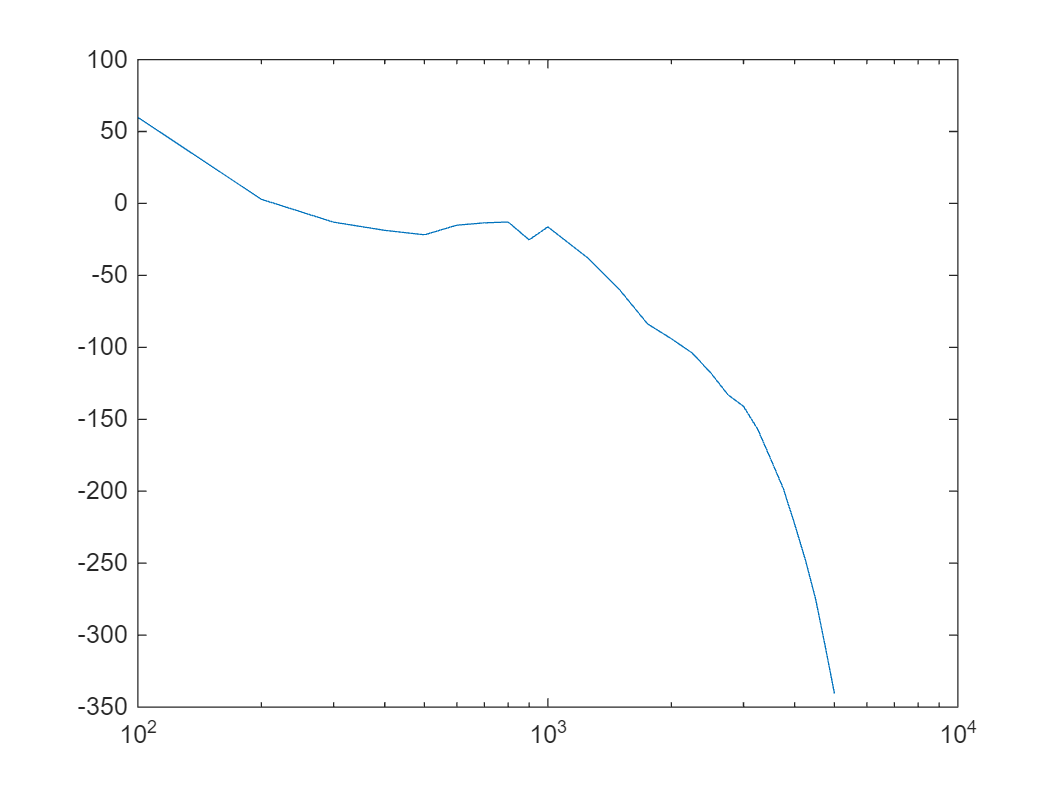

semilogx(freq, phase);

response = tran.*exp(1i*phase*pi/180);
Ts = 4*1e-5; % your sampling time
w=freq*2*pi; %convert Hz to rad/sec 

gfr = idfrd(response,w,Ts);

G=tfest(gfr,2);

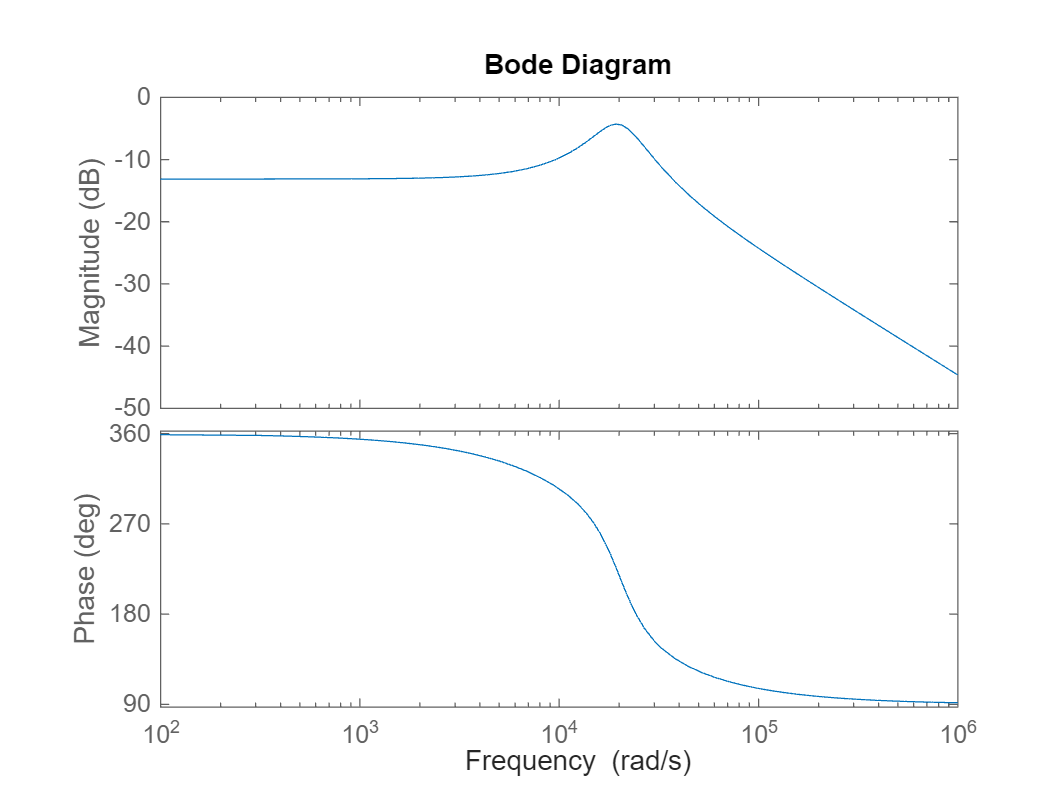

bodeplot(G)

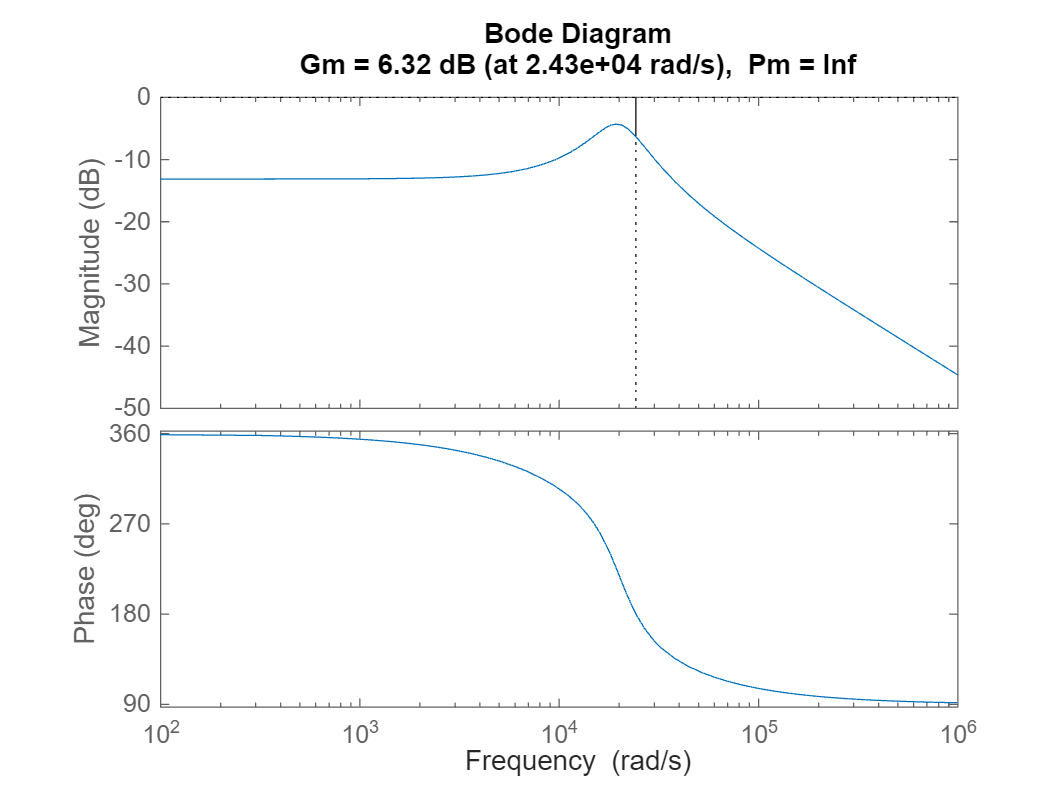

margin(G)

% Initial values for the constants
C1 = 220e-9;    % 1 nF
C = 100e-9;     % 1 nF
R1 = 1e3;    % 10 kΩ
R2 = 50;  % 51.6 kΩ
R = 3900;      % 1 MΩ
R3 = 100;    % 10 MΩ
r = 1200;      % 998 Ω
Q = 0.46;      % Example quality factor

numerator = [(C1/C)^2, (1/C)*(1/R1 - r/(R*R3)), 1/(C^2*R*R2)];
denominator = [1, 1/(Q*C*R), 1/(C^2*R^2)];

% Create the transfer function
comp = tf(numerator, denominator);

a = 600;
b = 602;
c = 3;
d = 3;
k = 1;
comp = k*tf([1 (a+b) a*b], [1 2*c c^2]);

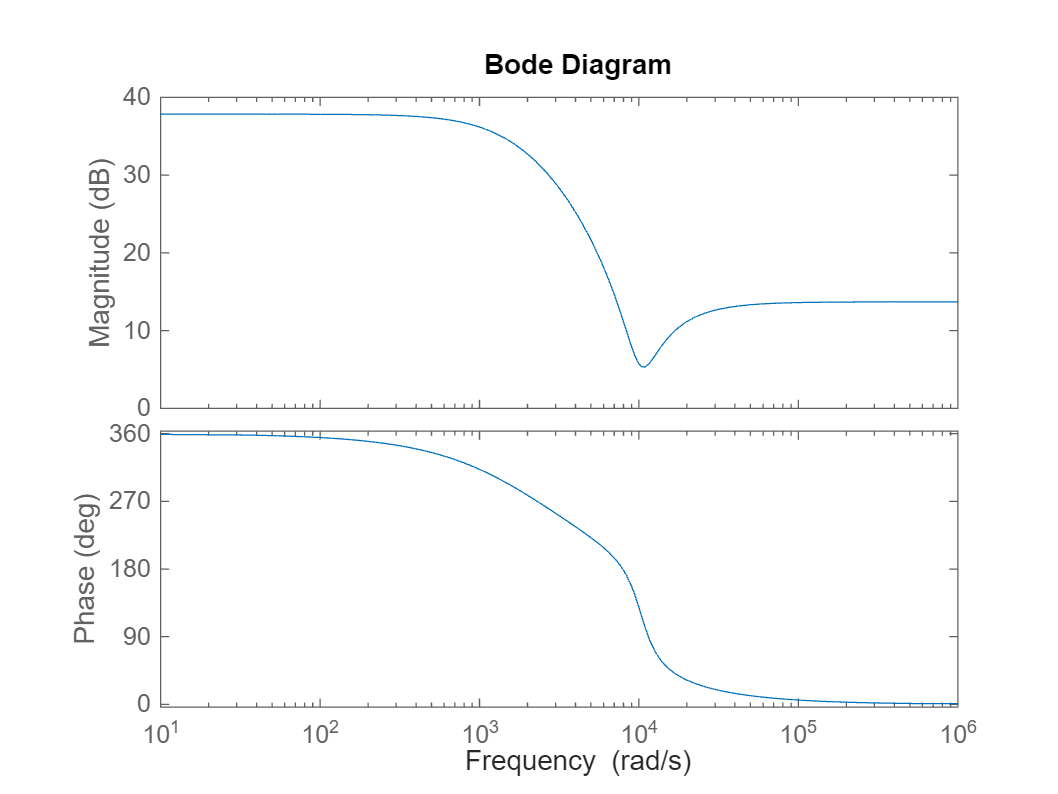

bodeplot(comp)

comp_sys = G*comp;
comp_sys_inclosedloop = comp_sys/(1 + comp_sys);
val = 20*log10(abs(evalfr(comp_sys,2*3.14*100*1j)));

val

val = 24.0248

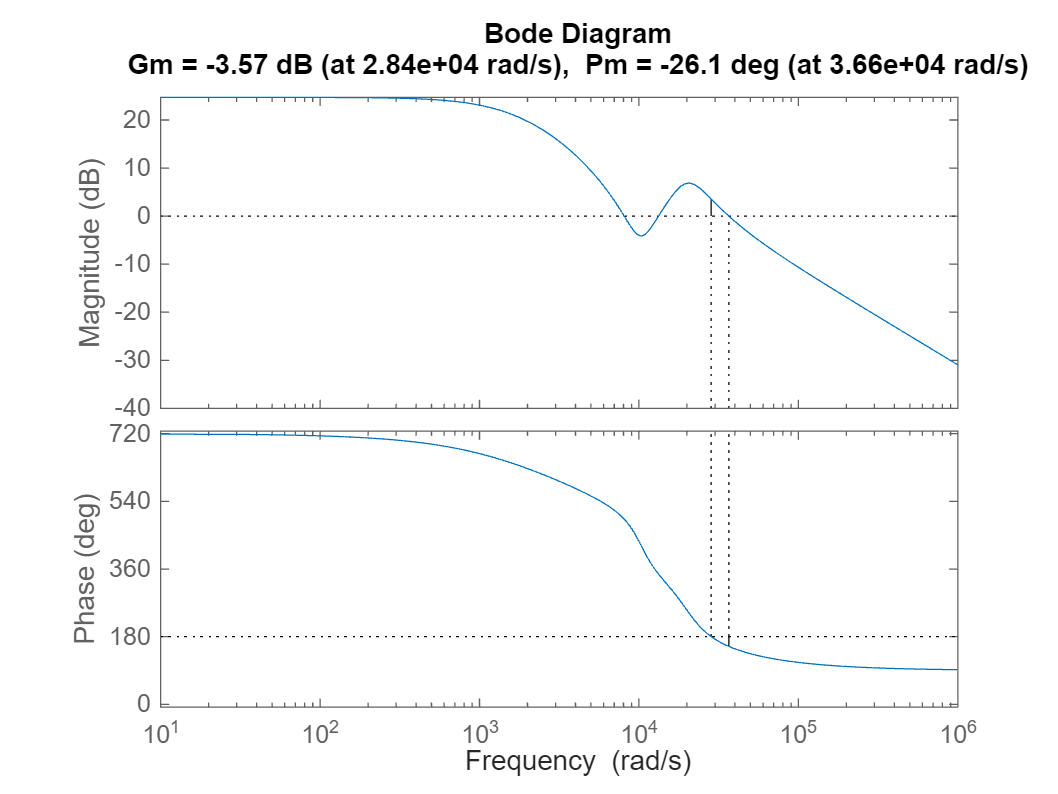

margin(comp_sys);

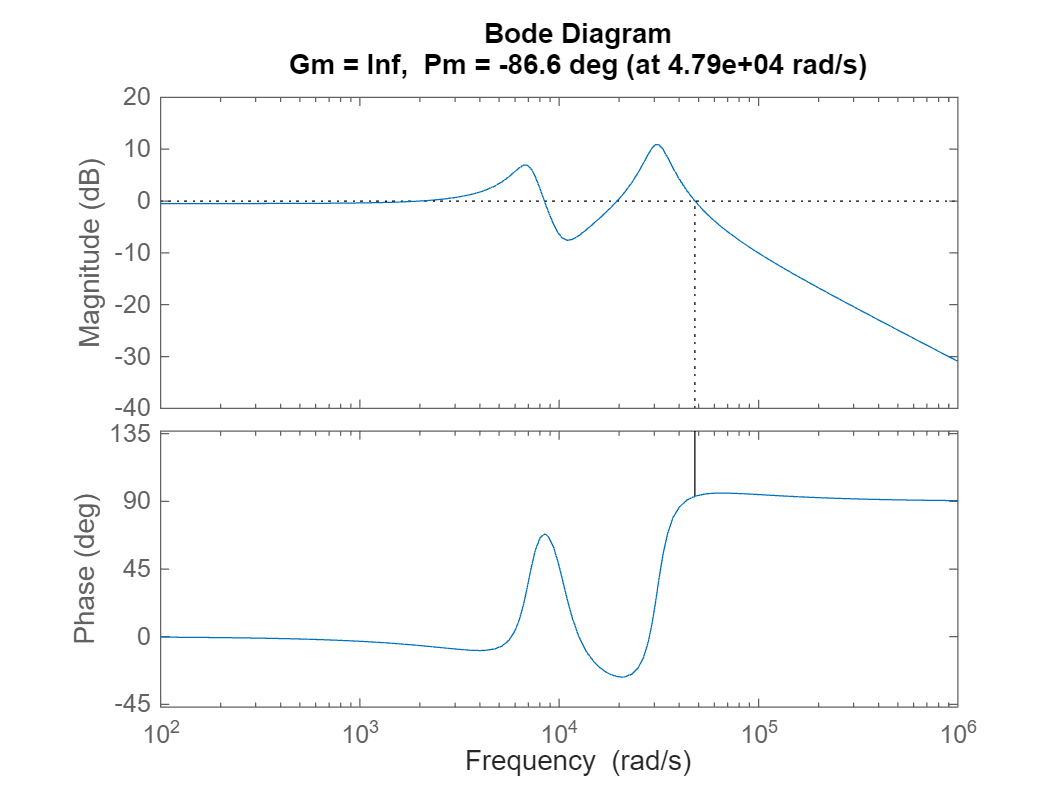

margin(comp_sys_inclosedloop)

    % Initial values for the constants
    C1 = 220e-9;    % 1 nF
    C = 100e-9;     % 1 nF
    R1 = 1e3;    % 10 kΩ
    R2 = 50;  % 51.6 kΩ
    R = 3900;      % 1 MΩ
    R3 = 100;    % 10 MΩ
    r = 2200;      % 998 Ω
    Q = 0.5;      % Example quality factor

    numerator = [(C1/C)^2, (1/C)*(1/R1 - r/(R*R3)), 1/(C^2*R*R2)];
    denominator = [1, 1/(Q*C*R), 1/(C^2*R^2)];

    % Create the transfer function
    sys = tf(numerator, denominator);

disp(sys)

  tf with properties:

       Numerator: {[4.8400 -4.6410e+04 5.1282e+08]}
     Denominator: {[1 5.1282e+03 6.5746e+06]}
        Variable: 's'
         IODelay: [0]
      InputDelay: [0]
     OutputDelay: [0]
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: [0]
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



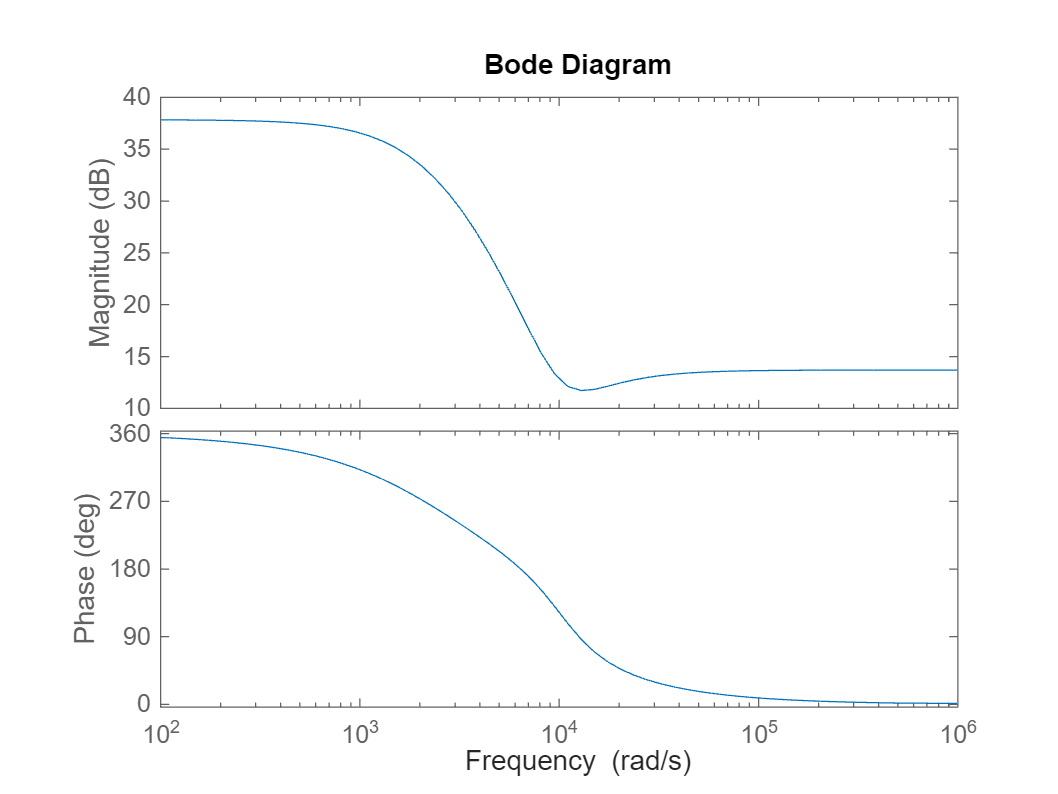

bodeplot(sys)

numerator = 26;
denominator

C1 = 1e-9;    % 1 nF
C = 1e-9;     % 1 nF
R1 = 10e3;    % 10 kΩ
R2 = 51.6e3;  % 51.6 kΩ
R = 1e6;      % 1 MΩ
R3 = 10e6;    % 10 MΩ
r = 998;      % 998 Ω
Q = 0.5;      % Example quality factor

numerator = [(C1/C)^2, (1/C)*(1/R1 - r/(R*R3)), 1/(C^2*R*R2)];
denominator = [1, 1/(Q*C*R), 1/(C^2*R^2)];

% Create the transfer function
compensator = tf(numerator, denominator);

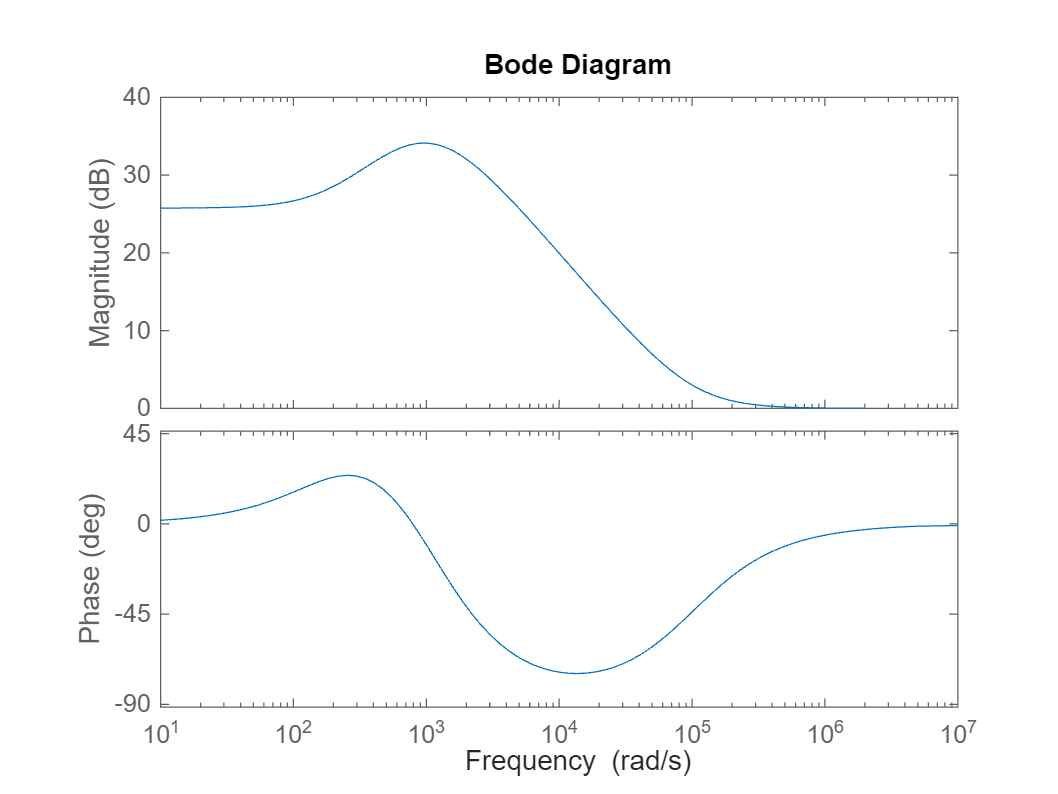

bodeplot(compensator)

numerator = [1];
denominator = [1, 10];

des = tf(numerator, denominator);

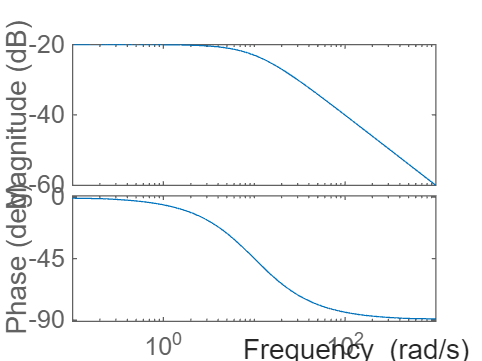

bodeplot(des)

compensated_sys = G*compensator;
compensated_sys_inclosedloop = compensated_sys/(1 + compensated_sys);
value = 20*log10(abs(evalfr(compensated_sys,2*3.14*100*1j)));

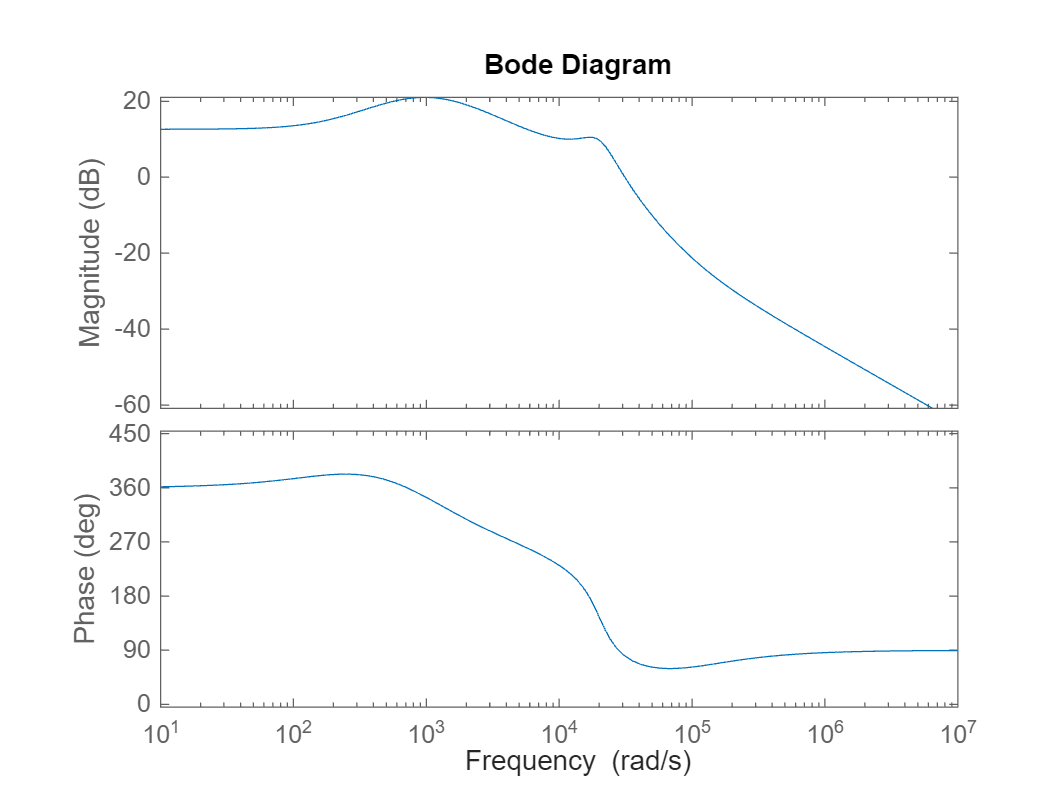

bodeplot(compensated_sys)

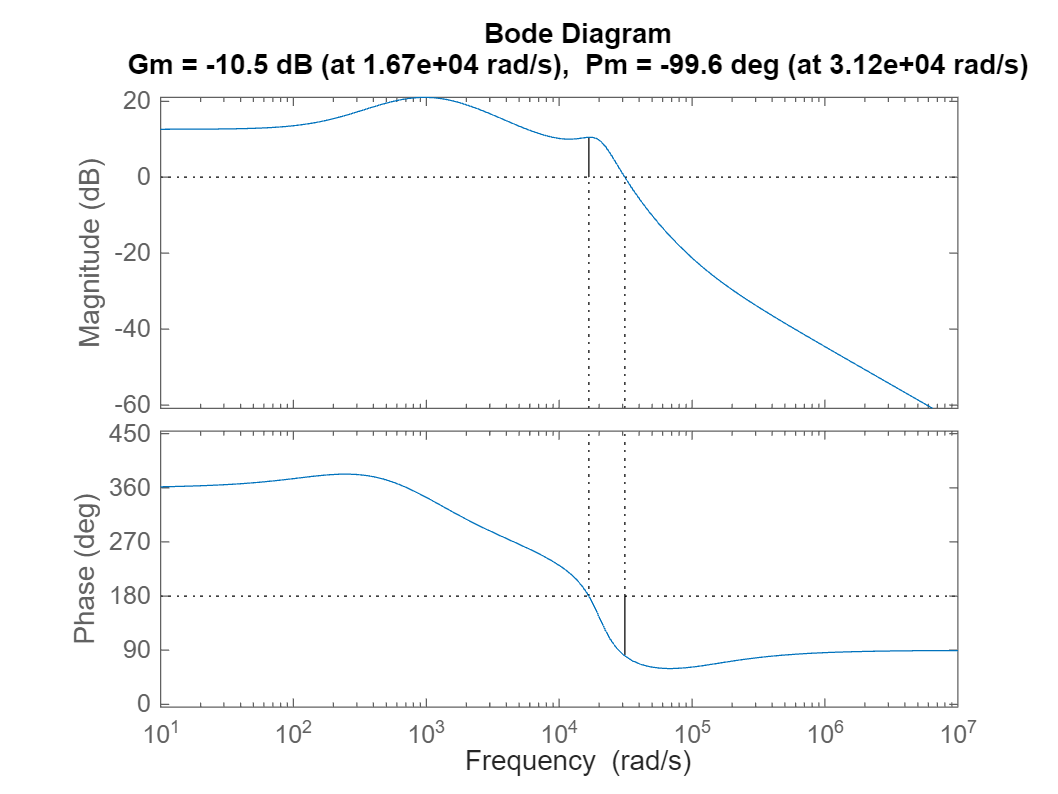

margin(compensated_sys)

value

value = 20.3350